# Part I - Creating a Byte-Pair Encoding (BPE) Tokenizer from Scratch in MATLAB

## Introduction

Tokenization is a critical component in the creation and training of Large Language Models (LLMs) because it converts text (input) into a numerical format, which is essential for implementing the attention mechanism. Tokenization serves two primary functions:

- Converting text to numbers and vice versa, and 

- Compressing the data.

**Why is compression necessary?**

The attention heads in the transformer architecture have a limited context length, which restricts the size of the matrix to manage computational complexity during training. By compressing more text into a smaller representation, the model can capture more information from the input text.

**However, as a direct result of this compression, LLMs may struggle with:**

- Spelling words accurately

- Processing strings (e.g., reversing a string)

- Performing well in non-English languages (e.g., Japanese)

- Executing simple arithmetic operations

- Understanding programming languages effectively

In addition,

- LLMs abruptly stop processing when they encounter the string `<|endoftext|>`.

**Objectives of this Notebook**

- **Understand the Tokenizer's Role in LLMs:** Explore the core function of tokenizers within Large Language Models to gain a deeper understanding of their operation.

- **Build Tokenizer Components from Scratch:** Develop the individual components of a tokenizer from the ground up.

- **Train and Evaluate the Tokenizer:** Train the final tokenizer to showcase its effectiveness in compressing text and converting it into numerical formats.

## Text Encoding

Let's begin with a straightforward example using a simple raw text:

rawText = 'Hello world';
disp(rawText)

Hello world


How can we transform this simple text into numerical representations?

### ASCII

One possible approach is to use the American Standard Code for Information Interchange (ASCII) character encoding. ASCII consists of 128 code points (7 bits), including only 95 printable characters. It was partially developed from telegraph code. ASCII encodes 128 specified characters into seven bits, covering the digits 0-9, lowercase letters a-z, uppercase letters A-Z, and various punctuation symbols.

However, the limitation of ASCII is its restricted character set, which lacks support for non-English language symbols, including emojis and other important symbols such as scientific notations.

### UNICODE

- Unicode is another text encoding standard, maintained by the Unicode Consortium, designed to support text representation across all of the world's writing systems that can be digitized. Unicode includes encoding for 3,790 emojis and has the capability to encode up to 1.1 million characters.

Why can't we use Unicode code points as our tokens?

- The Unicode standard defines 149,813 characters, resulting in an excessively large vocabulary.

- Additionally, Unicode is continuously evolving, which could lead to inconsistencies over time.

**Thus, a more efficient solution is needed.**

- Unicode offers three encoding formats: 

- UTF-8

- UTF-16

- UTF-32

The numbers indicate the bits used in the encoding process, with UTF-16 and UTF-32 using 16 and 32 bits, respectively. However, UTF-8 is unique because it is not of fixed length (ranging from 8 to 32 bits), providing backward compatibility with all UTF formats, making it the most widely used encoding.

### UTF-8

UTF-8 encodes code points using one to four bytes, depending on the value of the code point. The following table illustrates how UTF-8 encodes each point, with the characters u to z representing the bits of the code point:

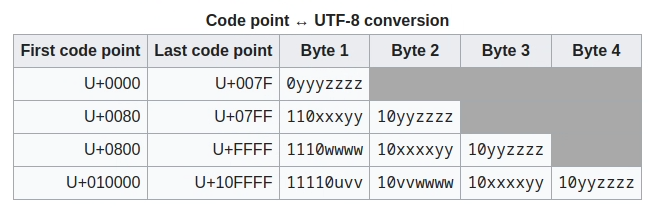

In UTF-8, the first 128 code points, corresponding to the ASCII set, require 1 byte (8 bits) for encoding. The subsequent 1,920 code points are encoded using 2 bytes (16 bits).

In MATLAB, we can encode text in UTF-8 using the `unicode2native()` and `native2unicode()` functions. These functions support characters from non-English languages as well.

disp(unicode2native('Ｕｎｉｃｏｄｅ! 🅤🅝🅘🅒🅞🅓🅔‽ 🇺‌🇳‌🇮‌🇨‌🇴‌🇩‌🇪! 😄', 'UTF-8'))

   239   188   181   239   189   142   239   189   137   239   189   131   239   189   143   239   189   132   239   189   133    33    32   240   159   133   164   240   159   133   157   240   159   133   152   240   159   133   146   240   159   133   158   240   159   133   147   240   159   133   148   226   128   189    32   240   159   135   186   226   128   140   240   159   135   179   226   128   140   240   159   135   174   226   128   140   240   159   135   168   226   128   140   240   159   135   180   226   128   140   240   159   135   169   226   128   140   240   159   135   170    33    32   240   159   152   132



disp(native2unicode([239	188	181	239	189	142	239	189	137	239	189	131	239	189	143	239	189	132	239	189	133	33	32	240	159	133	164	240	159	133	157	240	159	133	152	240	159	133	146	240	159	133	158	240	159	133	147	240	159	133	148	226	128	189	32	240	159	135	186	226	128	140	240	159	135	179	226	128	140	240	159	135	174	226	128	140	240	159	135	168	226	128	140	240	159	135	180	226	128	140	240	159	135	169	226	128	140	240	159	135	170	33	32	240	159	152	132]))

Ｕｎｉｃｏｄｅ! 🅤🅝🅘🅒🅞🅓🅔‽ 🇺‌🇳‌🇮‌🇨‌🇴‌🇩‌🇪! 😄


## Implementing Byte-pair Encoding

Byte-Pair Encoding (BPE) is a popular subword tokenization technique that iteratively merges the most frequent pairs of bytes or characters, effectively compressing and encoding text data. BPE efficiently tokenizes the input text by iteratively merging the most frequent pair of bytes or characters. 

Let's begin with the following text as an example, sourced from the "Commercial MATLAB" section of the page titled "[A Brief History of MATLAB](https://www.mathworks.com/company/technical-articles/a-brief-history-of-matlab.html)".

rawText = "In 1983, Little suggested the creation of a commercial product based on MATLAB. The IBM® PC had been introduced only two years earlier. It was barely powerful enough to run a program like MATLAB, but Little anticipated its evolution. He left his job, bought a Compaq® PC clone at Sears, moved into the hills behind Stanford, and with my encouragement, wrote a new and extended version of MATLAB in C. A friend, Steve Bangert, worked on the new MATLAB in his spare time.";
rawText = char(rawText); % treat each character separately
tokens = unicode2native(rawText); % tokens vector
disp(['Number of UTF-8 code points: ', num2str(length(rawText))])

Number of UTF-8 code points: 469


disp(['Number of tokens: ', num2str(length(tokens))])

Number of tokens: 471


Please note that the original length (number of UTF-8 code points) is greater than the number of tokens. This is because while most simple ASCII characters correspond to a single byte (8-bits), Unicode characters can be encoded with multiple bytes (up to 4 bytes). Consequently, the encoded size can be larger than the raw code points.

The main concept of the Byte-Pair Encoding (BPE) algorithm can be simplified as follows:

1. Calculate the frequency of each pair of characters.

2. Create a new token for the most frequent pair and replace all its occurrences with this new token.

3. Repeat the process until either no pairs occur more than once (natural termination) or a user-defined number of iterations has been reached (user-defined termination).

Let's create a new function to calculate the pair-wise token byte statistics:

function stats = getBytePairStatistics(tokens, opts)
    % This function calculates statistics for pair-wise token bytes

      Pairs       Occurence Freq.
    __________    _______________

    101     32          12       
    100     32          11       
    110     32           9       
     44     32           8       
     32     97           8       
    101    100           7       
    111    110           7       
     32    116           6       
    116     32           6       
     32     98           6       
    101    110           6       
    115     32           6       
    116    101           5       
     32    111           5       
    101    114           5       
     32    105           5       
    105    110           5       
     97    114           5       
     32    101           5       
     97    110           5       
    110    100           5       
    105    116           4       
    116    104           4       
    104    101           4       
    101     97           4       
    116    10

    %
    % Input:

Most common pair: ("e", " ")


    %   tokens - A vector of token strings
    %
    % Output:
    %   stats - A cell array containing the pair-wise byte statistics
    arguments
        tokens
        opts.DescendingOrder = false;
    end

    % Initialize the stats dictionary
    pairs = {};
    freq = [];
    numPairs = length(tokens)-1;

    % Iterate over all the bytes and find the byte pair of bytes gthat
    % occur most frequently
    for i = 1:numPairs
        pair = [tokens(i) tokens(i+1)];

        % Check if the pair exist in the current look-up table (lut), if
        % exist increment the frequency value, otherwise add the pair into
        % the lut.
        idx = cellfun(@(x) isequal(x, pair), pairs);
        if any(idx)
            freq(idx) = freq(idx) + 1;
        else
            pairs = cat(1,pairs, pair);

Original input: [5  6  7  7  6  0  1  2  3  7  2  6  7  8]


            freq = cat(1,freq, 1);

Processed output: [5  99   7   6   0   1   2   3   7   2  99   8]


        end
    end

    % If opts.DescendingOrder is true, order the pairs and frequencies in
    % descending order of the occurence frequencies
    if opts.DescendingOrder
       [freq, ordFreqIdx] = sort(freq, 'descend');
       pairs = pairs(ordFreqIdx);
    end
    stats = {cell2mat(pairs), freq};
end

Let's utilize the function `getBytePairStatistics()` to display the byte-pair statistics for our tokens:

stats = getBytePairStatistics(tokens, DescendingOrder=true);

Merge #1 | Top pair: (101, 32) | Frequency: 12 | Replace token:  257

--------------------
Terminated: max iterations


disp(table(stats{1}, stats{2},'VariableNames',{'Pairs', 'Occurence Freq.'}))

Original input: [73  110   32   49   57   56   51   44   32   76  105  116  116  108  101   32  115  117  103  103  101  115  116  101  100   32  116  104  101   32   99  114  101   97  116  105  111  110   32  111  102   32   97   32   99  111  109  109  101  114   99  105   97  108   32  112  114  111  100  117   99  116   32   98   97  115  101  100   32  111  110   32   77   65   84   76   65   66   46   32   84  104  101   32   73   66   77  194  174   32   80   67   32  104   97  100   32   98  101  101  110   32  105  110  116  114  111  100  117   99  101  100   32  111  110  108  121   32  116  119  111   32  121  101   97  114  115   32  101   97  114  108  105  101  114   46   32   73  116   32  119   97  115   32   98   97  114  101  108  121   32  112  111  119  101  114  102  117  108   32  101  110  111  117  103  104   32  116  111   32  114  117  110   32   97   32  112  114  111  103  114   97  109   32  108  105  107  101   32   77   65   84   76   65   66   44   32 

As observed above, the pair `[101 32]` occurs most frequently in the text. This corresponds to the characters `e` (ASCII 101) followed by a space (ASCII 32).

disp(['Most common pair: ("', native2unicode(stats{1}(1,1)),'", "',native2unicode(stats{1}(1,2)),'")'])

Original input size: 471


Now that we have calculated the byte-pair statistics, we can proceed to replace the pairs with new unique tokens (minted tokens). Let's begin by writing a function replacePairWithToken() to replace a specific pair with an arbitrary token:

function output = replacePairWithToken(input, pair, token)

Encoded output: [73  110   32   49   57   56   51   44   32   76  105  116  116  108  257  115  117  103  103  101  115  116  101  100   32  116  104  257   99  114  101   97  116  105  111  110   32  111  102   32   97   32   99  111  109  109  101  114   99  105   97  108   32  112  114  111  100  117   99  116   32   98   97  115  101  100   32  111  110   32   77   65   84   76   65   66   46   32   84  104  257   73   66   77  194  174   32   80   67   32  104   97  100   32   98  101  101  110   32  105  110  116  114  111  100  117   99  101  100   32  111  110  108  121   32  116  119  111   32  121  101   97  114  115   32  101   97  114  108  105  101  114   46   32   73  116   32  119   97  115   32   98   97  114  101  108  121   32  112  111  119  101  114  102  117  108   32  101  110  111  117  103  104   32  116  111   32  114  117  110   32   97   32  112  114  111  103  114   97  109   32  108  105  107  257   77   65   84   76   65   66   44   32   98  117  116   32 

    % This function replaces all occurrences of a specified pair with a new token.

Encoded output size: 459


    % Inputs:
    %   input - The input text represented as a vector of bytes.

   101    32   257



    %   pair  - A two-element vector representing the pair to be replaced.
    %   token - The new token that will replace the pair.
    
    % Pre-allocation
    output = [];
    p = 1; % pointer


The first MATLAB® was not a programming language; it was a simple interactive matrix calculator. There were no programs, no toolboxes, no graphics. And no ODEs or FFTs.

In this Cleve’s Corner, I’ll describe some milestones in the evolution of MATLAB from those simple beginnings.

Mathematical Origins
The mathematical basis for the first version of MATLAB was a series of research papers by J. H. Wilkinson and 18 of his colleagues, published between 1965 and 1970 and later collected in Handbook for Automatic Computation, Volume II, Linear Algebra, edited by Wilkinson and C. Reinsch. These papers present algorithms, implemented in Algol 60, for solving matrix linear equation and eigenvalue problems.

EISPACK and LINPACK
In 1970, a group of researchers at Argonne National Laboratory proposed to the U.S. National Science Foundation (NSF) to “explore the methodology, costs, and resources required to produce, test, and disseminate high-quality mathematical software and to test, certify, diss

    % Iterate over the input text
    while p <= length(input)
        if p < length(input) && input(p) == pair(1) && input(p+1) == pair(2)
            output = cat(2, output, token);
            p = p + 2; % increase the pointer by 2
        else

The first MATLAB® was not a programming language; it was a simple interactive matrix calculator. There were no programs, no toolboxes, no graphics. And no ODEs or FFTs. In this Cleve’s Corner, I’ll describe some milestones in the evolution of MATLAB from those simple beginnings. Mathematical Origins The mathematical basis for the first version of MATLAB was a series of research papers by J. H. Wilkinson and 18 of his colleagues, published between 1965 and 1970 and later collected in Handbook for Automatic Computation, Volume II, Linear Algebra, edited by Wilkinson and C. Reinsch. These papers present algorithms, implemented in Algol 60, for solving matrix linear equation and eigenvalue problems. EISPACK and LINPACK In 1970, a group of researchers at Argonne National Laboratory proposed to the U.S. National Science Foundation (NSF) to “explore the methodology, costs, and resources required to produce, test, and disseminate high-quality mathematical software and to test, certify, dissemi

            output = cat(2, output, single(input(p)));
            p = p + 1; % increase the pointer by 1
        end

Original input size: 11908


    end

Merge #1 | Top pair: (101, 32) | Frequency: 310 | Replace token:  257
Merge #2 | Top pair: (105, 110) | Frequency: 195 | Replace token:  258
Merge #3 | Top pair: (100, 32) | Frequency: 168 | Replace token:  259
Merge #4 | Top pair: (97, 116) | Frequency: 148 | Replace token:  260
Merge #5 | Top pair: (32, 116) | Frequency: 139 | Replace token:  261

--------------------
Terminated: max iterations


end

Encoded output size: 10948


Let's test the `replacePairWithToken()` function using a toy example:

testInput = [5 6 7 7 6 0 1 2 3 7 2 6 7 8];

   101    32   257
   105   110   258
   100    32   259
    97   116   260
    32   116   261



testOutput = replacePairWithToken(testInput, [6 7], 99);
fprintf('Original input: [%s]\n', num2str(testInput));

Compression ratio: 1.09X


fprintf('Processed output: [%s]\n', num2str(testOutput));

We can combine both `getBytePairStatistics()` and `replacePairWithToken()` to replace the top pairs with new tokens:

function [encoded, vocab] = encoderFunction(tokens, opts)
    % This function replaces the top pairs in the text with new tokens for a given number of iterations.
    % Inputs:
    %   tokens - The input tokens represented as a vector of bytes.
    arguments

Original input: [2   6   7   9   2   1   3   4  99   9   3  99   2  10  99]


        tokens {mustBeNumeric}

Processed output: [2   6   7   9   2   1   3   4  -1  -2   9   3  -1  -2   2  10  -1  -2]


        opts.VocabSize = -1  % turned off by default
        opts.TokenID = 257;  % UTF-8 encoding
        opts.Verbose = false % display the progress
    end
    
    % Pre-allocation
    vocab = [];
    if opts.VocabSize > 0
        nMerges = opts.VocabSize - (opts.TokenID - 1);
        assert(nMerges > 0, "opts.VocabSize - (opts.TokenID - 1) must be positive.")
    else
        nMerges = Inf;
    end
    stopFlag = false; 

    % Step 1: Calculate the byte-pair statistics
    stats = getBytePairStatistics(tokens, DescendingOrder=true);

    % Step 2: Iterate over the tokens and replace the byte-pairs with new tokens
    i = 1;
    encoded = tokens; % copy the original tokens vector
    while ~stopFlag && i <= nMerges

        % Step 3: Merge pairs into a new token
        topPair = single(stats{1}(i,:));
        encoded = replacePairWithToken(encoded, topPair, opts.TokenID);
        vocab = cat(1, vocab, [topPair opts.TokenID]); % build a look-up table
        
        % Display information

Input tokens vector size: 10948


        if opts.Verbose

Output tokens vector size: 11908


            fprintf('Merge #%d | Top pair: (%d, %d) | Frequency: %d | Replace token: % d\n', i, topPair(1), topPair(2), stats{2}(i), opts.TokenID);
        end

        % Step 4: Calculate the byte-pair statistics again
        stats = getBytePairStatistics(encoded, DescendingOrder=true);


Are the `tokens` and `decoded` equal?: yes

        % Step 5: Check if the merging ended naturally
        if sum(stats{2}) == length(stats{2})
            stopFlag = true;

The first MATLAB® was not a programming language; it was a simple interactive matrix calculator. There were no programs, no toolboxes, no graphics. And no ODEs or FFTs. In this Cleve’s Corner, I’ll describe some milestones in the evolution of MATLAB from those simple beginnings. Mathematical Origins The mathematical basis for the first version of MATLAB was a series of research papers by J. H. Wilkinson and 18 of his colleagues, published between 1965 and 1970 and later collected in Handbook for Automatic Computation, Volume II, Linear Algebra, edited by Wilkinson and C. Reinsch. These papers present algorithms, implemented in Algol 60, for solving matrix linear equation and eigenvalue problems. EISPACK and LINPACK In 1970, a group of researchers at Argonne National Laboratory proposed to the U.S. National Science Foundation (NSF) to “explore the methodology, costs, and resources required to produce, test, and disseminate high-quality mathematical software and to test, certify, dissemi

The first MATLAB® was not a programming language; it was a simple interactive matrix calculator. There were no programs, no toolboxes, no graphics. And no ODEs or FFTs. In this Cleve’s Corner, I’ll describe some milestones in the evolution of MATLAB from those simple beginnings. Mathematical Origins The mathematical basis for the first version of MATLAB was a series of research papers by J. H. Wilkinson and 18 of his colleagues, published between 1965 and 1970 and later collected in Handbook for Automatic Computation, Volume II, Linear Algebra, edited by Wilkinson and C. Reinsch. These papers present algorithms, implemented in Algol 60, for solving matrix linear equation and eigenvalue problems. EISPACK and LINPACK In 1970, a group of researchers at Argonne National Laboratory proposed to the U.S. National Science Foundation (NSF) to “explore the methodology, costs, and resources required to produce, test, and disseminate high-quality mathematical software and to test, certify, dissemi

            % Display status (if enabled)
            if opts.Verbose
                fprintf('\n--------------------\n');
                fprintf('Terminated: no pairs repeat more than once\n');
            end
        end

Are the `rawText` and `decodedText` equal?: yes

        
        % Increment i and tokenID
         i = i + 1;
        opts.TokenID = opts.TokenID + 1;
    end

    % Display status (if enabled)
    if opts.Verbose
        fprintf('\n--------------------\n');
        if i > nMerges
            fprintf('Terminated: max iterations\n');
        end
    end
end

Let's test the `encoderFunction()` with the tokens derived from our text. Given that our final vocabulary size is `257`, we will perform a single byte-pair merge. This means that all occurrences of the pair `[101 32]` (representing "e " or "e" followed by a space) should be replaced with the new token `257`.

Another important point to note is the number of merges, which is a hyperparameter. A large number of merges will take longer and yield a shorter output token sequence, whereas a smaller number of merges will result in shorter execution times with a longer output token sequence.

[encoded, vocab] = encoderFunction(tokens, VocabSize=257, TokenID=257, Verbose=true);
fprintf('Original input: [%s]\n', num2str(tokens));
fprintf('Original input size: %d\n', length(tokens));
fprintf('Encoded output: [%s]\n', num2str(encoded));
fprintf('Encoded output size: %d\n', length(encoded));

Note that the `encoderFunction()` also returns a look-up table for the mergings (`vocab`), which contains crucial information about the mapping and will be used during decoding.

disp(vocab)

### Testing our Byte-Pair Encoder with a Larger Text

Let's find a larger text to test our encoder function by taking an entire blog post as input. To simplify the process, we'll read the text input from a .txt file as follows:

formatSpec = '%c';
fileID = fopen('cleve_blog_post.txt','r'); % open the text file (read-only)
rawText = fscanf(fileID, formatSpec);
disp(rawText)
fclose(fileID); % close the text file

% Pre-process text: Replace the newline operators (both linefeed and
% carriage return) with a space
rawText = regexprep(rawText,'[\n\r]+',' ');
disp(rawText)
% Pre-process text: Convert raw text into tokens
tokens = unicode2native(rawText, "UTF-8"); % tokens vector
fprintf('Original input size: %d\n', length(tokens));
[encoded, vocab] = encoderFunction(tokens, VocabSize=261, TokenID=257, Verbose=true);
fprintf('Encoded output size: %d\n', length(encoded));
disp(vocab)

Based on the original (`tokens`) and encoded token (`encoded`) vectors, we can determine the compression ratio using the following method:

fprintf('Compression ratio: %.2fX\n', length(tokens)/length(encoded));

The process described above is called **training the tokenizer**. It's important to note that the tokenizer is a completely separate and independent module from the Large Language Model (LLM). The tokenizer has its own dataset of text, which can be different from the dataset used to train the LLM. The training algorithm for the tokenizer is based on Byte-Pair Encoding (BPE). The main role of the tokenizer is depicted in the following diagram:

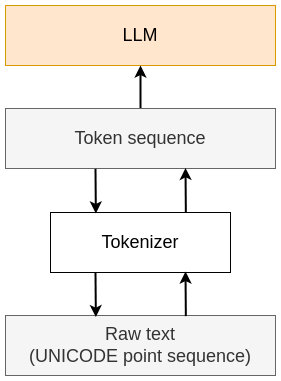

As can be seen from the figure above, the tokenizer translates raw text into token sequences and vice versa. The LLM only ever sees the tokens and never directly deals with any text.

If the tokenizer is trained for a specific target language, the token sequence in that language will be shorter, depending on the number of iterations of the Byte-Pair Encoding process. This is crucial because LLMs have a limited attention context length that they can remember or work on, due to the very large computational complexity involved.

### Decoding

In the previous section, we implemented an encoder function that transforms raw text into a token sequence. In this section, we'll focus on creating a decoder function, which reverses this process by converting a token sequence back into raw text.

#### Main Operation of the Decoder Function

The purpose of the decoder function is to rebuild the original text from a sequence of integers (`tokens`) using a lookup table (`vocab`). Below is an overview of how the decoder function works:

**Input:**

- A sequence of integers (tokens) within the range `[0, vocabSize]`.

- A lookup table (`vocab`) that maps each token back to its corresponding byte-pair or character sequence.

**Process:**

- Iterate through the token sequence.

- For each token, utilize the lookup table to retrieve the corresponding byte-pair or character sequence.

- Concatenate these sequences to reconstruct the original text.

**Output:**

- The reconstructed original text.

function output = replaceTokenWithPair(input, token, pair)
% replacePairWithToken Replaces byte-pairs with corresponding tokens.
    %
    % Inputs:
    %   input - A vector of byte-pairs
    %   token - tokenID that will be used instead of the pair
    %   pair  - A pair that will be replaced with the token
    %
    % Output:
    %   output - A vector of tokens corresponding to the compressed
    %   expression of the input
    
    % Pre-allocation
    output = [];

    % Iterate over the input
    for p = 1:length(input)
        if input(p) == token
            output = cat(2, output, pair);
        else
            output = cat(2, output, input(p));
        end
    end
end

To test the `replacePairWithToken()` function, we can set up a scenario where we replace every occurrence of `99` with the pair `[-1 -2]`.

testInput = [2 6 7 9 2 1 3 4 99 9 3 99 2 10 99];
testToken = 99;
testPair = [-1 -2];
testOutput = replaceTokenWithPair(testInput, testToken, testPair);
fprintf('Original input: [%s]\n', num2str(testInput));
fprintf('Processed output: [%s]\n', num2str(testOutput));

Now that the `replaceTokenWithPair()` function is ready, we can integrate it into the decoder function.

function decoded = decoderFunction(encoded, vocab)
% decoderFunction Decodes a sequence of tokens into byte-pairs.
    %
    % Inputs:
    %   encoded - A vector of tokens that need to be decoded vocav   
    %   vocab - A vector where first two columns is the pair and the last column is
    %   the corresponding tokenID
    %
    % Output:
    %   decoded - A vector of byte-pairs corresponding to the de-compressed tokens
    arguments
        encoded {mustBeNumeric}
        vocab
    end

    % Pre-allocation
    decoded = encoded; % copy encoded vector
    vocab = flipud(vocab);

    % Iterate over the encoded vector
    for i = 1:size(vocab, 1)
        % Replace the items in the reverse-order of their inclusion
        decoded = replaceTokenWithPair(decoded, vocab(i, 3), vocab(i, 1:2));
    end
end

Now, let's test our `decoderFunction()` using the actual token dataset.

decoded = decoderFunction(encoded, vocab);
fprintf('Input tokens vector size: %d\n', length(encoded));
fprintf('Output tokens vector size: %d\n', length(decoded));

Let's compare the token vectors before encoding (`tokens`) and after byte-pair encoding (`decoded`).

if isequal(tokens, decoded)
    fprintf('Are the `tokens` and `decoded` equal?: yes');
else
    fprintf('Are the `tokens` and `decoded` equal?: no');
end

Since the `tokens` and `decoded` vectors are identical, we can proceed to convert the `decoded` token vector back into text as our final step.

decodedText = native2unicode(decoded);
disp(rawText)
disp(decodedText)

The final step is to compare the `rawText` with the `decodedText`, as demonstrated below:

if isequal(rawText, decodedText)
    fprintf('Are the `rawText` and `decodedText` equal?: yes');
else
    fprintf('Are the `rawText` and `decodedText` equal?: no');
end